imdata1 = imread("book.jpg");
imgray1 = rgb2gray(imdata1);
% im1 = im2double(imgray1);

imdata2 = imread("red_chair.jpg");
imgray2 = rgb2gray(imdata2);
% im2 = im2double(imgray2);

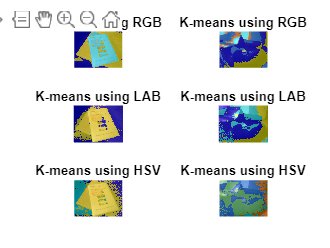

% RGB
num_colors = 3;
L1 = imsegkmeans(imdata1,num_colors);
B1 = labeloverlay(imdata1,L1);
L2 = imsegkmeans(imdata2,5);
B2 = labeloverlay(imdata2,L2);

figure();
subplot(3,2,1)
imshow(B1)
title("K-means using RGB")
subplot(3,2,2)
imshow(B2)
title("K-means using RGB")

% LAB
imlab1 = rgb2lab(imdata1);
% ab1 = imlab1(:,:,2:3);
ab1 = im2single(ab1);
pixel_labels1 = imsegkmeans(ab1,2,NumAttempts=3);
B3 = labeloverlay(imdata1,pixel_labels1);

imlab2 = rgb2lab(imdata2);
% ab2 = imlab2(:,:,2:3);
ab2 = im2single(ab2);
pixel_labels2 = imsegkmeans(ab2,3,NumAttempts=3);
B4 = labeloverlay(imdata2,pixel_labels2);

subplot(3,2,3)
imshow(B3)
title("K-means using LAB")
subplot(3,2,4)
imshow(B4)
title("K-means using LAB")

% HSV
imhsv1 = rgb2hsv(imdata1);
% hsv1 = imhsv1(:,:,1);
hsv1 = im2single(hsv1);
pixel_labels1 = imsegkmeans(hsv1,3,NumAttempts=3);
B5 = labeloverlay(imdata1,pixel_labels1);

imhsv2 = rgb2hsv(imdata2);
% hsv2 = imhsv2(:,:,1);
hsv2 = im2single(hsv2);
pixel_labels2 = imsegkmeans(hsv2,4,NumAttempts=3);
B6 = labeloverlay(imdata2,pixel_labels2);

subplot(3,2,5)
imshow(B5)
title("K-means using HSV")
subplot(3,2,6)
imshow(B6)
title("K-means using HSV")

**Results for RGB color space**

Image 1: 3 clusters

Image 2: 5 clusters

**Results for LAB color space**

Image 1: 2 clusters

Image 2: 3 clusters

**Results for HSV color space**

Image 1: 3 clusters

Image 2: 4 clusters

As shown above, I ended up using the RGB, LAB, and HSV parameters for my images. The LAB color space seems to be a lot more sensitive to changes in the number of clusters compared to the RGB and HSV color spaces. The LAB color space also seems more sensitive to different light sources. 

The RGB color space has the least amount of noise, and seems to work the best out of the three color spaces because of that. 

The HSV color space seemed to perform the worst out of the three, having the least amount of detail and the most noise.